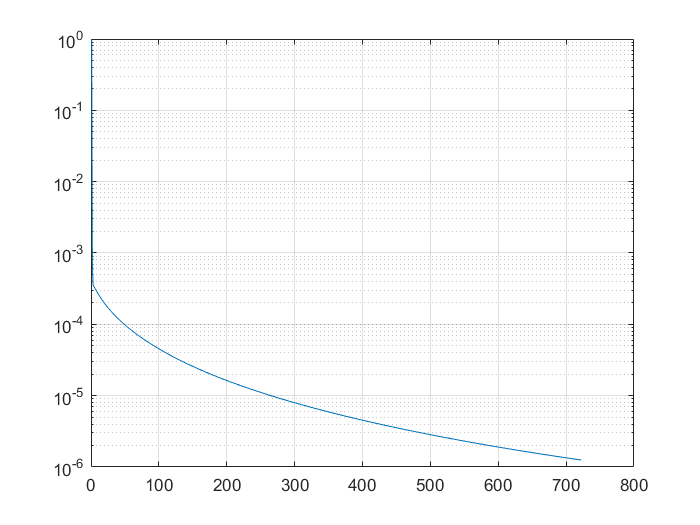

%Reading the images and performing data type conversions
imga = double(imread("characters\char1_a.bmp"));
imgb = double(imread("characters\char1_b.bmp"));
imgc = double(imread("characters\char1_c.bmp"));
imgd = double(imread("characters\char1_d.bmp"));
imge = double(imread("characters\char1_e.bmp"));
imgf = double(imread("characters\char1_f.bmp"));
imgg = double(imread("characters\char1_g.bmp"));
imgh = double(imread("characters\char1_h.bmp"));
imgi = double(imread("characters\char1_i.bmp"));
imgj = double(imread("characters\char1_j.bmp"));
imgk = double(imread("characters\char1_k.bmp"));
imgl = double(imread("characters\char1_l.bmp"));
imgm = double(imread("characters\char1_m.bmp"));
imgn = double(imread("characters\char1_n.bmp"));
imgo = double(imread("characters\char1_o.bmp"));
imgp = double(imread("characters\char1_p.bmp"));
imgq = double(imread("characters\char1_q.bmp"));
imgr = double(imread("characters\char1_r.bmp"));
imgs = double(imread("characters\char1_s.bmp"));
imgt = double(imread("characters\char1_t.bmp"));
imgu = double(imread("characters\char1_u.bmp"));
imgv = double(imread("characters\char1_v.bmp"));
imgw = double(imread("characters\char1_w.bmp"));
imgx = double(imread("characters\char1_x.bmp"));
imgy = double(imread("characters\char1_y.bmp"));
imgz = double(imread("characters\char1_z.bmp"));

%Reshape and normalize the matrix into a vector
imga = normc(reshape(imga, numel(imga),1));
imgb = normc(reshape(imgb, numel(imgb),1));
imgc = normc(reshape(imgc, numel(imgc),1));
imgd = normc(reshape(imgd, numel(imgd),1));
imge = normc(reshape(imge, numel(imge),1));
imgf = normc(reshape(imgf, numel(imgf),1));
imgg = normc(reshape(imgg, numel(imgg),1));
imgh = normc(reshape(imgh, numel(imgh),1));
imgi = normc(reshape(imgi, numel(imgi),1));
imgj = normc(reshape(imgj, numel(imgj),1));
imgk = normc(reshape(imgk, numel(imgk),1));
imgl = normc(reshape(imgl, numel(imgl),1));
imgm = normc(reshape(imgm, numel(imgm),1));
imgn = normc(reshape(imgn, numel(imgn),1));
imgo = normc(reshape(imgo, numel(imgo),1));
imgp = normc(reshape(imgp, numel(imgp),1));
imgq = normc(reshape(imgq, numel(imgq),1));
imgr = normc(reshape(imgr, numel(imgr),1));
imgs = normc(reshape(imgs, numel(imgs),1));
imgt = normc(reshape(imgt, numel(imgt),1));
imgu = normc(reshape(imgu, numel(imgu),1));
imgv = normc(reshape(imgv, numel(imgv),1));
imgw = normc(reshape(imgw, numel(imgw),1));
imgx = normc(reshape(imgx, numel(imgx),1));
imgy = normc(reshape(imgy, numel(imgy),1));
imgz = normc(reshape(imgz, numel(imgz),1));

P = [imga imgb imgc imgd imge imgf imgg imgh imgi imgj imgk imgl imgm imgn imgo imgp imgq imgr imgs imgt imgu imgv imgw imgx imgy imgz];
T = P;
const = 4*pi*1E-7;
L = 0.035;
W = zeros(numel(imga),numel(imga));
b = zeros(numel(imga),1);
size = numel(imga);
i =1;
mse_vector = [1];

%Applying LMS learning rule to update weight and bias until convergence
while mse_vector(i) >= const
    tracker = zeros(size,26);
    for m = 1:26
        a = (W * P( :,m)) + b;
        e = T( :,m) - a;
        tracker( :,m) = e;
        W = W + (2*L*e*transpose(P( :,m)));
        b = b + (2*L*e);
    end
    mse_vector(i+1) = mse(tracker);
    i = i+1;
end

%Plot the learning curve
semilogy(mse_vector)
grid on


%Correlation coefficient between network 
%output and desired target output

out = (W * P) + b;
value =[];

for o = 1:26
    for t =1:26
        value(o,t) = corr2(T( :,t),out(:,o));
    end
end

tabl = array2table(value, 'VariableNames', {'Out1', '0ut2','Out3', '0ut4', 'Out5', '0ut6', 'Out7', '0ut8','Out9', '0ut10','Out11', '0ut12', 'Out13', '0ut14', 'Out15', '0ut16', 'Out17', '0ut18','Out19', '0ut20', 'Out21', '0ut22', 'Out23', '0ut24', 'Out25', 'Out26'}, 'RowNames', sprintfc('Target %d', 1:26));
disp(tabl)

                   Out1         0ut2          Out3         0ut4         Out5          0ut6          Out7          0ut8         Out9         0ut10         Out11         0ut12         Out13         0ut14         Out15         0ut16         Out17         0ut18       Out19        0ut20         Out21        0ut22       Out23       0ut24        Out25        Out26  
                 _________    _________    __________    _________    _________    __________ 

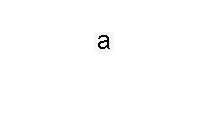


%Reshape and display the output vector
outa = (W*P( :,1)) + b;
outk = (W*P( :,11)) + b;
outy = (W*P( :,25)) + b;

imshow(reshape(outa, 20, 20),[]);

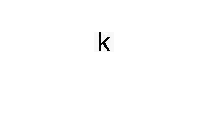

imshow(reshape(outk,20,20),[]);

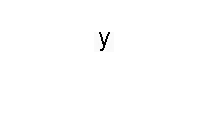

imshow(reshape(outy,20,20),[]);